# Filtros

## Importar datos

Importar "S9....mat" de Utils4SP

load("../../Utils4SP/Datasets/S9_Filtros.mat")

%Preproc
atmosfera(:,["Pres_kpa" "Temp_C" "Hum_perc"])=fillmissing(atmosfera(:,["Pres_kpa" "Temp_C" "Hum_perc"]),"linear");

T1=datetime(2021,05,20);
T2=datetime(2021,05,24);
index=atmosfera.DateTime>T1 &...
    atmosfera.DateTime<T2;
atmosfera=atmosfera(index,:);

%Insertar campo de dia y noche
dateTime_Hours=hour(atmosfera.DateTime);
day_night=discretize(dateTime_Hours,[0 8 18 24],'categorical',["Noche" "Dia" "Noche"]);
atmosfera.dayNight=day_night;

## Promedio móvil

- Aplicar promedio móvil a todos los campos de atmósfera

- Comparar series de tiempo antes y después

- Comparar el contenido espectral antes y después del filtro

- Hacer un chart de dispersión y hacer nuevamente un ajuste. Comparar la calidad del ajuste respecto a la práctica de S5.

%Promedio móvil 
atmos_movMean_3=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},3);
atmos_movMean_100=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},100);
atmos_movMean_1000=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},1000);
atmos_movMean_10000=movmean(atmosfera{:,["Pres_kpa" "Temp_C" "Hum_perc"]},10000);

%Visualizar temperatura sin filtro y con filtro
figure
plot(atmosfera.DateTime,[ ...
    atmosfera.Temp_C ...
    atmos_movMean_3(:,2) ...
    atmos_movMean_100(:,2) ...
    atmos_movMean_1000(:,2)],'LineWidth',2)

xlim([T1 T2])
legend("Original","Orden 3","Orden 100","Orden 1000" )
ylabel("Temperatura °C")
title("Temperatura en mi casa")
grid on

%Contenido espectral
N=numel(atmosfera.Temp_C);
[Pxx,f]=periodogram([ ...
    atmosfera.Temp_C ...
    atmos_movMean_3(:,2) ...
    atmos_movMean_100(:,2) ...
    atmos_movMean_1000(:,2)],flattopwin(N),N*10,1/5);

%Visualización de contenido espectral
figure
plot(f,pow2db(Pxx))
legend("Original","Orden 3","Orden 100","Orden 1000" )
title("Contenido espectral de la temperatura")
ylabel("PSD dB")
xlabel("Frecuencia [Hz]")
grid on

%Ajuste
[fit_line_nofil,gof]=fit(atmosfera.Temp_C,atmosfera.Hum_perc,'poly2')

fit_line_nofil =      Linear model Poly2:
     fit_line_nofil(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =     0.01825  (0.01627, 0.02023)
       p2 =      -3.193  (-3.29, -3.097)
       p3 =       106.8  (105.7, 107.9)

gof = struct with fields:
           sse: 4.8121e+06
       rsquare: 0.7307
           dfe: 68754
    adjrsquare: 0.7307
          rmse: 8.3660


[fit_line_fil,gof]=fit(atmos_movMean_10000(:,2),atmos_movMean_10000(:,3),'poly2')

fit_line_fil =      Linear model Poly2:
     fit_line_fil(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =    -0.09061  (-0.09436, -0.08686)
       p2 =       2.496  (2.322, 2.67)
       p3 =       35.01  (33.02, 36.99)

gof = struct with fields:
           sse: 2.8725e+06
       rsquare: 0.4669
           dfe: 68754
    adjrsquare: 0.4669
          rmse: 6.4637


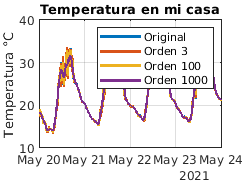

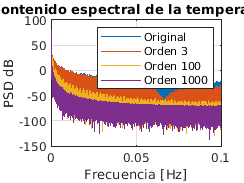



%Dispersión filtrada Hum vs temp
figure
%Original
scatter(atmosfera.Temp_C,atmosfera.Hum_perc,'Marker','.')
hold on
plot(fit_line_nofil)
%Filtro orden 1000
scatter(atmos_movMean_1000(:,2),atmos_movMean_1000(:,3),'Marker','.')
plot(fit_line_fil)

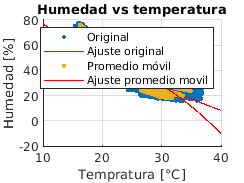

hold off
%xlim([10 50])
%ylim([0 100])
xlabel("Tempratura [°C]")
ylabel("Humedad [%]")
grid on
title("Humedad vs temperatura")
legend("Original","Ajuste original","Promedio móvil","Ajuste promedio movil")

%El promeido móvil no fue bueno para quitar las variaciones en el chart de
%dispersión de humedad contra temperatura.
%Se necesita hacer una discriminación más detallada. Dividir entre día,
%noche y por día calendario.


## Detrend

Hacer detrend a las componentes x & y del campo magnético de Cassini con las siguientes técnicas:

- Restando promedio móvil

- Ajustando un polinomio

- Usando detrend

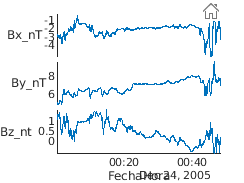

figure
stackedplot(Cassini(:,["FechaHora" "Bx_nT" "By_nT" "Bz_nt"]),'XVariable',"FechaHora")


v_muestras=1:numel(Cassini.By_nT);
%Promedio movil y polinomio
cassini_movmean=movmean(Cassini{:,["Bx_nT" "By_nT"]},50);
fit_cassini=fit(v_muestras',Cassini.By_nT,'poly5');


%Detend (restar promedio movil y polinomio)
cassini_detrend_movmean=Cassini.By_nT-cassini_movmean(:,2);
cassini_detrend_poly=Cassini.By_nT-fit_cassini(v_muestras);
%Detrend por la función "detrend"
cassini_detrend_detrend=detrend(Cassini.By_nT,5);

Aplicar el espectrograma a la magnitud de Cassini antes y después del detrend. Observar por qué es importante quitar las bajas frecuencias (Incluido el DC).

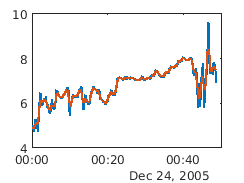

%Visualizacion de datos originales y promedio movil
figure
plot(Cassini.FechaHora,[Cassini.By_nT cassini_movmean(:,2) ],'LineWidth',2)

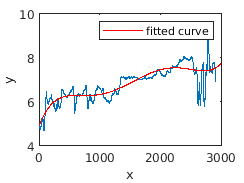


%Visualización de datos y ajuste polinomial
figure
plot(Cassini.By_nT)
hold on
plot(fit_cassini)

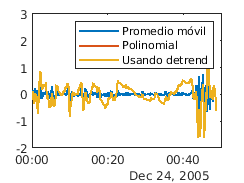


%Visualizacion de señales sin tendencia en tiempo
figure
plot(Cassini.FechaHora,[cassini_detrend_movmean cassini_detrend_poly cassini_detrend_detrend],'LineWidth',1.5)
legend("Promedio móvil","Polinomial","Usando detrend")

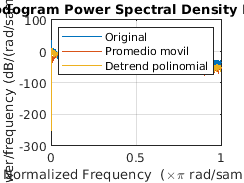


%Visualizacion en frecuencia
figure
periodogram([Cassini.Bx_nT cassini_detrend_movmean cassini_detrend_detrend])
legend("Original","Promedio movil","Detrend polinomial")

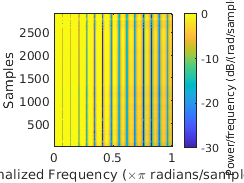



N_spectr=round(numel(Cassini.By_nT)/100);
%Espectrograma de señal original y de señal detrended
figure
spectrogram(Cassini.By_nT,rectwin(N_spectr),[],[])
caxis([-30 0])

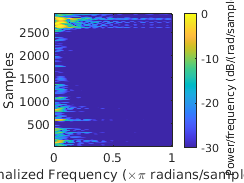

% %señal detrended
figure
spectrogram(cassini_detrend_movmean,rectwin(N_spectr),[],[])
caxis([-30 0])

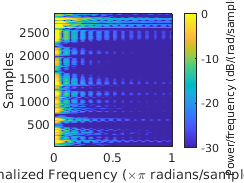


figure
spectrogram(cassini_detrend_detrend,rectwin(N_spectr),[],[])
caxis([-30 0])

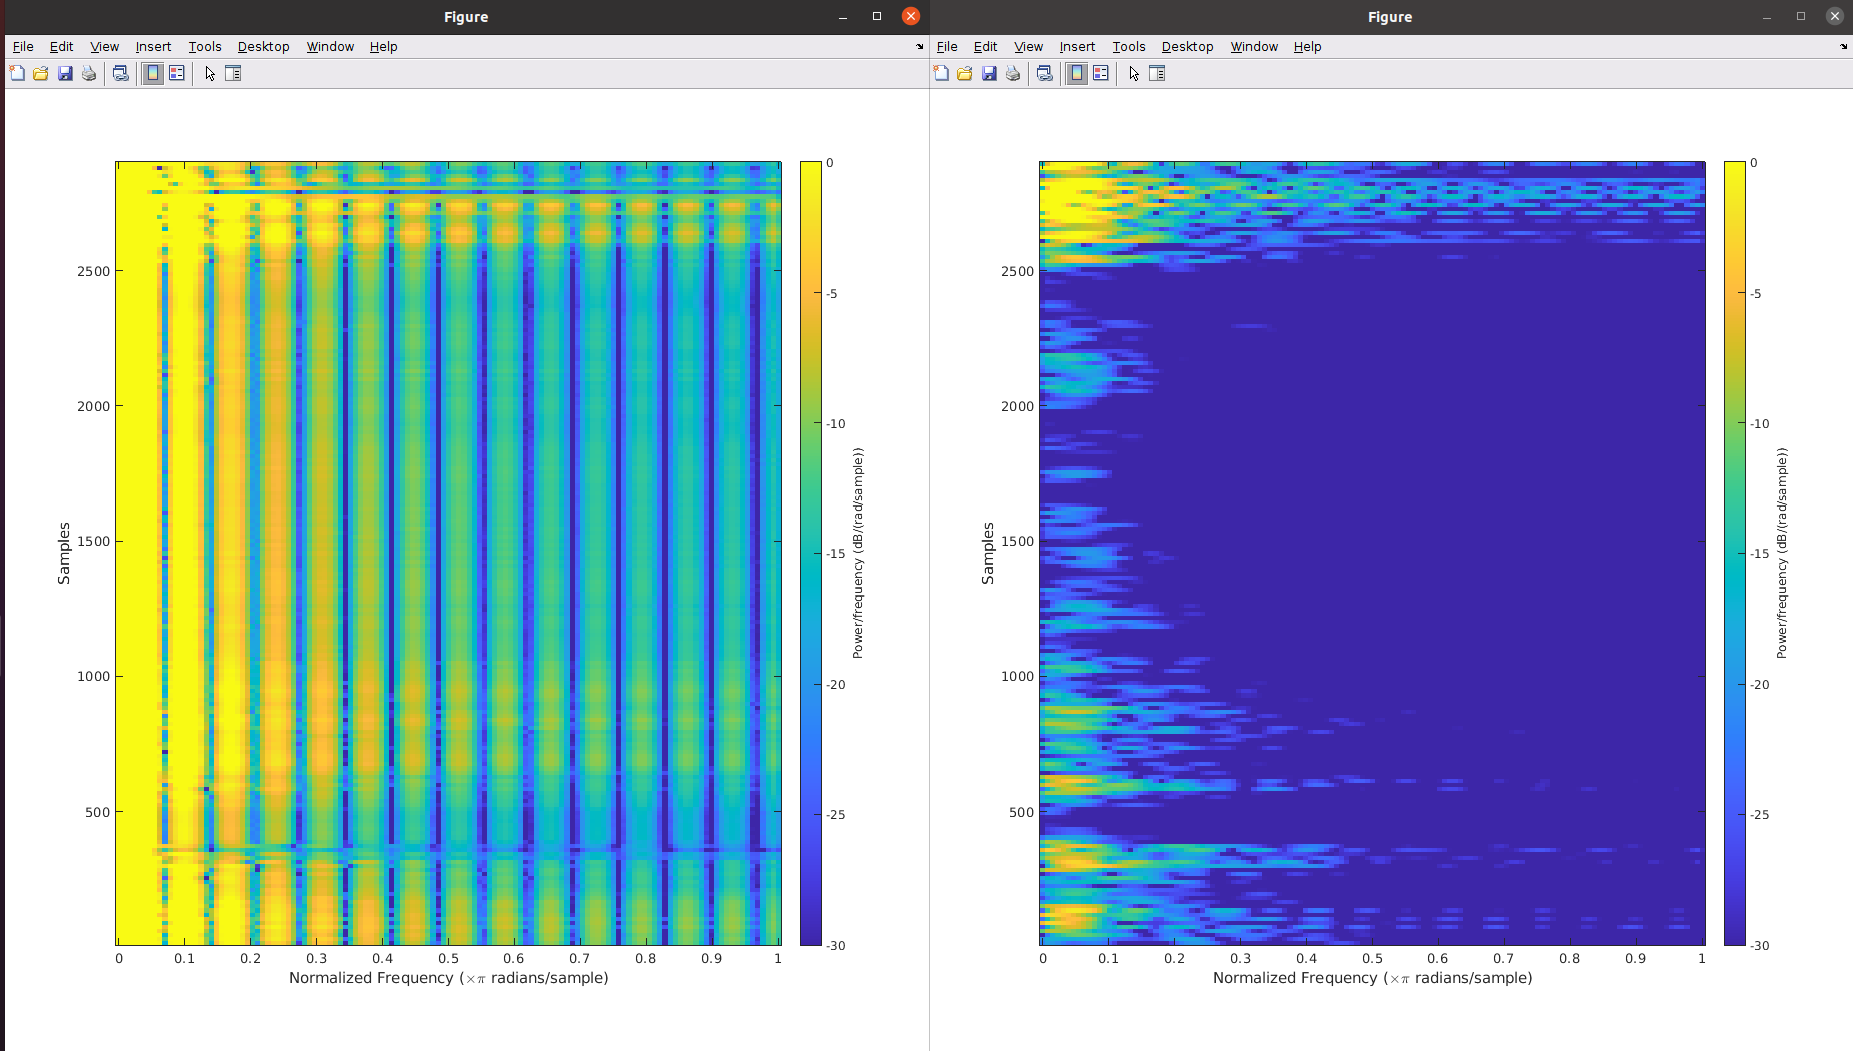

Izquierda: Derrame espectral por la señal DC// Derecha: Señal sin derrame

## Espectrograma vs paper

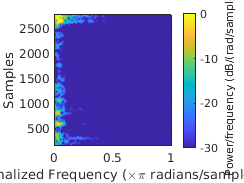

N_spectr=round(numel(Cassini.By_nT)/10);

figure
spectrogram(cassini_detrend_movmean,flattopwin(N_spectr),round(N_spectr-2),1024)
caxis([-30 0])
set(gca,'XScale','Log')

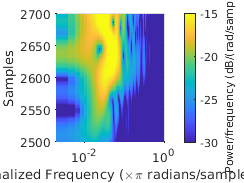

ylim([2500 2700])

## No lineales

Contexto: Los datos de RVB son producto de un sensor altamente inestable y ruidoso.

Hacer la reconstrucción facial de los datos de RVB:

- Remover NaN's

- Usar un filtro no lineal para quitar la mayor cantidad de ruido

- Usar promedio móvil para dar el toque final

## Experimento

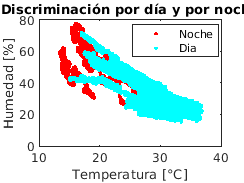

figure
gscatter(atmosfera.Temp_C,atmosfera.Hum_perc,atmosfera.dayNight,[],'.')
title("Discriminación por día y por noche")
xlabel("Temperatura [°C]")
ylabel("Humedad [%]")

index=atmosfera.dayNight=="Dia";
figure
gscatter(atmosfera.Temp_C(index),atmosfera.Hum_perc(index),day(atmosfera.DateTime(index)),[],'.')

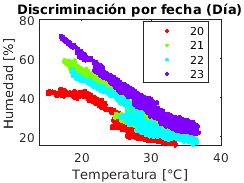

xlabel("Temperatura [°C]")
ylabel("Humedad [%]")
title("Discriminación por fecha (Día)")

index=atmosfera.dayNight=="Noche";
figure
gscatter(atmosfera.Temp_C(index),atmosfera.Hum_perc(index),day(atmosfera.DateTime(index)),[],'.')

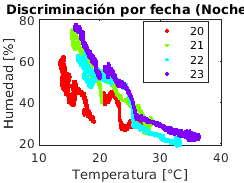

xlabel("Temperatura [°C]")
ylabel("Humedad [%]")
title("Discriminación por fecha (Noche)")